# Quickstart: Accessing Neuropixels Electrophysiology Data from the Allen Brain Observatory

This quickstart example demonstrates access and basic analysis of the Visual Coding Neuropixels dataset [1] from the Allen Brain Observatory [2].

### Accessing the Visual Coding Neuropixels Dataset

availSessions = bot.fetchSessions('ephys');
availProbes = bot.fetchProbes();
availChannels = bot.fetchChannels();
availUnits = bot.fetchUnits();

### Examining Sessions

#### Inspecting Available Sessions 

head(availSessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

#### Selecting Sessions of Interest

% select sessions with female subjects
filteredSessions = availSessions(availSessions.sex == "F",:);
% select sessions with wild-type subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:);
% select sessions designed to investigate functional connectivity
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 
disp(filteredSessions)

       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                              ephys_structure_acronyms                                              isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    _______________________________________________________________________________

#### Creating Session Objects

sessionUnderStudy = bot.session(filteredSessions(1,:)); 
sessionUnderStudy.info

ans = struct with fields:
                          id: 819186360
                  unit_count: 531
               channel_count: 1696
                 probe_count: 5
                session_type: functional_connectivity
                 age_in_days: 128
           fail_eye_tracking: 0
                         sex: F
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "APN; CA1; CA3; DG; HPF; LGd; LP; MB; NOT; POL; SCig; SCiw; SCop; SUB; VISam; VISl; VISpm; VISrl"
           isi_experiment_id: 809373390
         date_of_acquisition: 08-Feb-2019 09:02:25
                 specimen_id: 800249587
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


#### Inspecting Session Object Properties

disp(sessionUnderStudy)

  ephyssession with properties:

                              info: [1×1 struct]
                                id: 819186360
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: [1×18 string]

   Linked Items
                            probes: [5×23 table]
                          channels: [1696×29 table]
                             units: [531×51 table]

   Linked Item Derived Values


       channel_structure_intervals: [34×2 table]
         structurewise_unit_counts: [15×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_data_detailed: '[on demand]'
                      rig_metadata: '[on demand]'
                     running_speed: '[on demand]'
                session_start_time: '[on demand]'
                  spike_amplitudes: '[on demand]'
                       spike_times: '[on demand]'
               stimulus_conditions: '[on demand]'
                   stimulus_epochs: '[on demand]'
                    stimulus_names: '[on demand]'
            stimulus_presentations: '[on demand]'

   Linked File Values ('StimTemplatesGroup')
                stimulus_templates: '[on demand]'



### Group Analysis of Session Units

unitsTable = sessionUnderStudy.units;
head(unitsTable)

ans = 8×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

summary(unitsTable(:,"firing_rate"));

Description:  epoch_name_quality_metrics: complete_session - epoch_name_waveform_metrics: complete_session - quality: good - type: EPhys - published_at: 03-Oct-2019 - has_nwb: true 

Variables:

    firing_rate: 531×1 double

        Values:

            Min       0.096779
            Median      5.4277
            Max         46.996



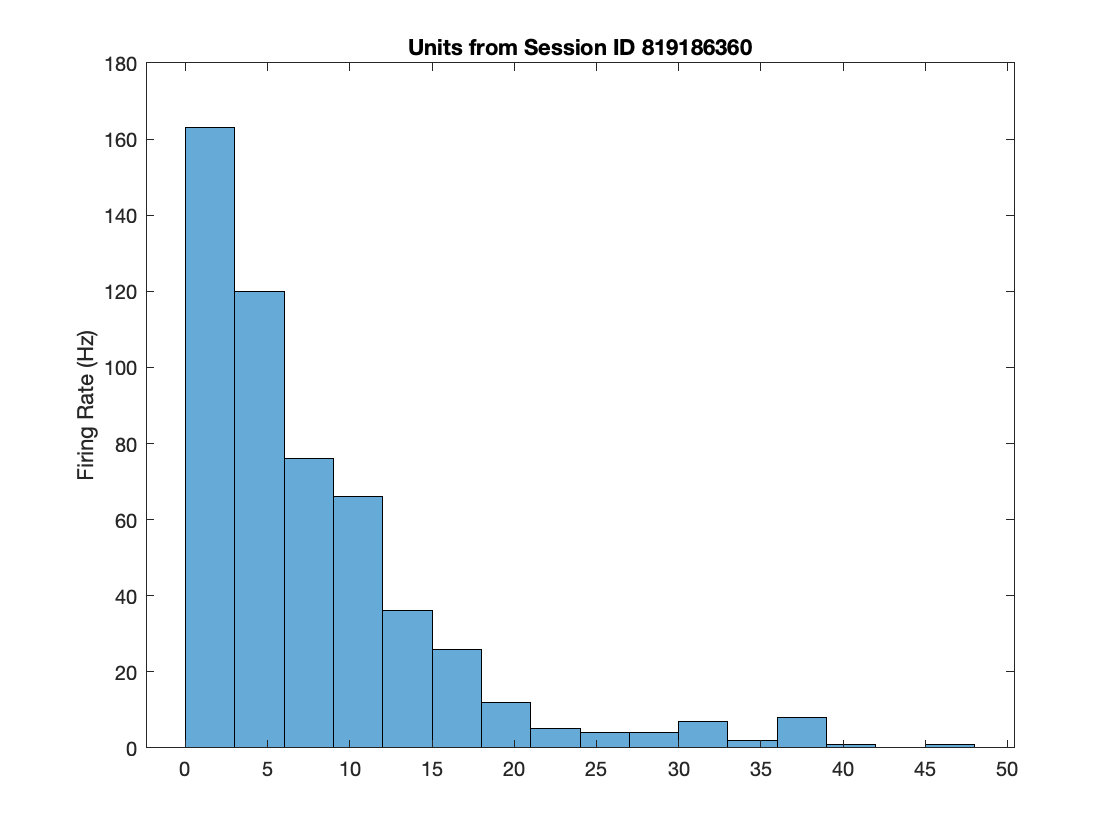

histogram(unitsTable.firing_rate);
ylabel('Firing Rate (Hz)');
title("Units from Session ID " + sessionUnderStudy.id);

### Examining Probes

probes = sessionUnderStudy.probes;
% obtain a `probe` object for the first probe
probe = bot.probe(probes(1, :))

probe =   ephysprobe with properties:

           info: [1×1 struct]
             id: 820311754
    linkedFiles: [1×1 table]

   Linked Items
        session: [1×1 bot.item.ephyssession]
       channels: [345×29 table]
          units: [81×51 table]

   Linked File Values ('LFPNWB')
        lfpData: '[on demand]'
        csdData: '[on demand]'


fieldnames(probe.info)

ans = 23×1 cell array
    {'id'                             }
    {'ephys_session_id'               }
    {'unit_count'                     }
    {'channel_count'                  }
    {'name'                           }
    {'session_type'                   }
    {'age_in_days'                    }
    {'air_channel_index'              }
    {'fail_eye_tracking'              }
    {'has_lfp_data'                   }
    {'lfp_sampling_rate'              }
    {'lfp_temporal_subsampling_factor'}
    {'phase'                          }
    {'sampling_rate'                  }
    {'sex'                            }
    {'surface_channel_index'          }
    {'genotype'                       }
    {'ephys_structure_acronyms'       }
    {'isi_experiment_id'              }
    {'date_of_acquisition'            }
    {'specimen_id'                    }
    {'specimen'                       }
    {'well_known_files'               }


#### Probe Low Frequency Data

head(probe.lfpData)

ans = 8×1 timetable
       Time       LocalFieldPotential
    __________    ___________________

    3.6356 sec       [1×77 single]   
    3.6364 sec       [1×77 single]   
    3.6372 sec       [1×77 single]   
    3.638 sec        [1×77 single]   
    3.6388 sec       [1×77 single]   
    3.6396 sec       [1×77 single]   
    3.6404 sec       [1×77 single]   
    3.6412 sec       [1×77 single]   


probe.csdData

ans = struct with fields:
                   data: [875×1 timetable]
    horizontalPositions: [384×1 double]
      verticalPositions: [384×1 double]


### Examining Channels

channels = sessionUnderStudy.channels;
% obtain a `channel` object for the first channel
channel = bot.channel(channels(1, :))

channel =   ephyschannel with properties:

       info: [1×1 struct]
         id: 849795978

   Linked Items
    session: [1×1 bot.item.ephyssession]
      probe: [1×1 bot.item.ephysprobe]
      units: [1×51 table]


fieldnames(channel.info)

ans = 29×1 cell array
    {'id'                               }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'unit_count'                       }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'anterior_posterior_ccf_coordinate'}
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'has_lfp_data'                     }
    {'left_right_ccf_coordinate'        }
    {'lfp_sampling_rate'                }
    {'lfp_temporal_subsampling_factor'  }
    {'local_index'                      }
    {'phase'                            }
    {'probe_horizontal_position'        }
    {'probe_name'                       }
    {'probe_vertical_position'          }
    {'sampling_rate'                    }
    {'sex'                              }
    {'surface_channel_index'            }
    {'genoty

### Examining Units

units = sessionUnderStudy.units;
units = units(units.ephys_structure_acronym == 'VISam', :)

units = 52×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

% obtain a `unit` object for the first unit
unit = bot.unit(units(1, :))

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 951133559

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]


fieldnames(unit.info)

ans = 51×1 cell array
    {'id'                               }
    {'ephys_channel_id'                 }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'L_ratio'                          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'amplitude_cutoff'                 }
    {'anterior_posterior_ccf_coordinate'}
    {'cumulative_drift'                 }
    {'d_prime'                          }
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'firing_rate'                      }
    {'has_lfp_data'                     }
    {'isi_violations'                   }
    {'isolation_distance'               }
    {'left_right_ccf_coordinate'        }
    {'lfp_temporal_subsampling_factor'  }
    {'max_drift'                        }
    {'nn_hit_rate'                      }
    {'nn_mis

### References

[1] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 